# **Introduction to Engineering and Programming with MATLAB**

**Lab 6 Signal Processing using MATLAB**

Instructor: Yuhong Zhang (Yuhong_zhang1@brown.edu)

**Signal Representation**

Creating and Visualizing Signals

**Time-domain Signal**: Create and plot signals in the time domain.

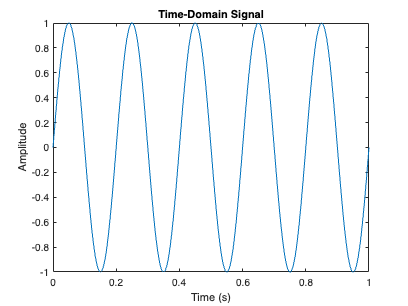

t = 0:0.001:1; % Time vector
f = 5; % Frequency in Hz
x = sin(2*pi*f*t); % Sine wave
plot(t, x);
title('Time-Domain Signal');
xlabel('Time (s)');
ylabel('Amplitude');

**Sampling**

**Sampling a Signal**: Sample a continuous signal to obtain a discrete signal.

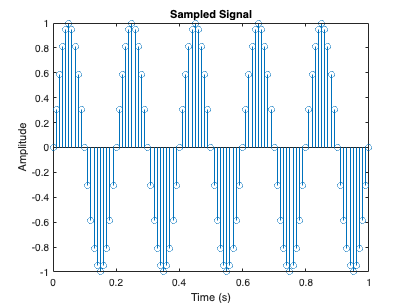

fs = 100; % Sampling frequency in Hz
t = 0:1/fs:1; % Time vector
x = sin(2*pi*5*t); % Sampled sine wave
stem(t, x);
title('Sampled Signal');
xlabel('Time (s)');
ylabel('Amplitude');

**Fourier Analysis**

**Compute and Plot FFT**: Transform a time-domain signal to the frequency domain.

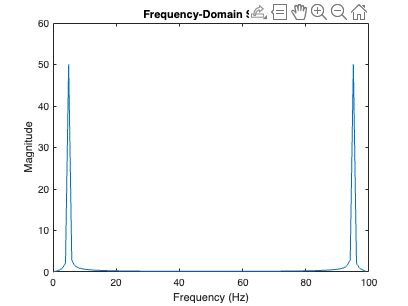

X = fft(x);
f = (0:length(X)-1)*fs/length(X); % Frequency vector
plot(f, abs(X));
title('Frequency-Domain Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

**Compute Inverse FFT**: Transform a frequency-domain signal back to the time domain.

x_reconstructed = ifft(X);
plot(t, x_reconstructed);
title('Reconstructed Time-Domain Signal');
xlabel('Time (s)');
ylabel('Amplitude');


**AM Modulation**: Modulate a signal using amplitude modulation.

carrier = cos(2*pi*50*t); % Carrier signal
am_signal = (1 + 0.5*x) .* carrier; % AM modulated signal
plot(t, am_signal);
title('AM Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');


**FM Modulation**: Modulate a signal using frequency modulation.

kf = 50; % Frequency sensitivity
fm_signal = cos(2*pi*50*t + kf * cumtrapz(t, x)); % FM modulated signal
plot(t, fm_signal);
title('FM Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');



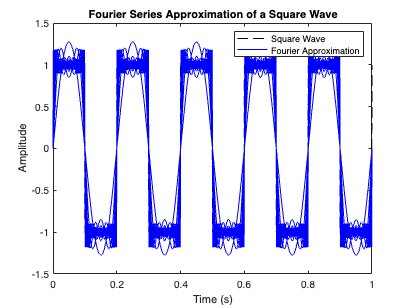

% Generate a square wave
t = 0:0.001:1; % Time vector
f = 5; % Frequency of the square wave
square_wave = square(2*pi*f*t); % Generate square wave

% Initialize plot
figure;
plot(t, square_wave, 'k--'); % Plot the original square wave
hold on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Fourier Series Approximation of a Square Wave');

% Fourier series decomposition and visualization
N = 100; % Number of sine waves to sum
approximation = zeros(size(t)); % Initialize the approximation

for k = 1:N
    if mod(k, 2) == 1 % Only odd harmonics
        % Calculate the k-th term of the Fourier series
        harmonic = (4/pi) * (1/k) * sin(2*pi*k*f*t);
        approximation = approximation + harmonic; % Add to approximation

        % Plot the current approximation
        plot(t, approximation, 'b');
        legend('Square Wave', 'Fourier Approximation');
        pause(0.3); % Pause for 0.1 seconds to visualize the process
    end
end

hold off;

Low Pass Filter

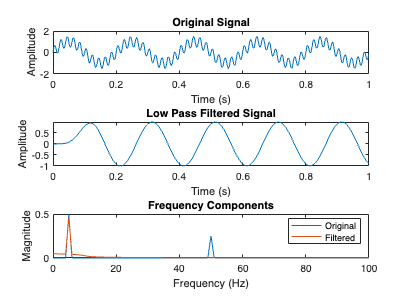

% Sample parameters
Fs = 1000; % Sampling frequency (Hz)
t = 0:1/Fs:1-1/Fs; % Time vector (1 second)
f = 5; % Frequency of the sine wave (Hz)

% Generate a sample signal (sine wave)
x = sin(2*pi*f*t) + 0.5*sin(2*pi*50*t); % A signal with two frequencies: 5 Hz and 50 Hz

% Low pass filter design
Fc = 10; % Cutoff frequency (Hz)
[b, a] = butter(6, Fc/(Fs/2), 'low'); % 6th order Butterworth filter

% Apply the low pass filter
y_low = filter(b, a, x);

% FFT of the original and filtered signals
N = length(x);
X = fft(x);
Y_low = fft(y_low);

f = (0:N-1)*(Fs/N); % Frequency vector

% Plot the results
figure;
subplot(3,1,1);
plot(t, x);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, y_low);
title('Low Pass Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(f, abs(X)/N);
hold on;
plot(f, abs(Y_low)/N);
title('Frequency Components');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original', 'Filtered');
xlim([0 100]); % Limit frequency range for clarity

High Pass Filter

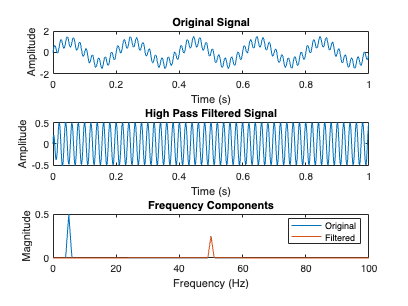

% High pass filter design
Fc = 20; % Cutoff frequency (Hz)
[b, a] = butter(6, Fc/(Fs/2), 'high'); % 6th order Butterworth filter

% Apply the high pass filter
y_high = filter(b, a, x);

% FFT of the filtered signal
Y_high = fft(y_high);

% Plot the results
figure;
subplot(3,1,1);
plot(t, x);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, y_high);
title('High Pass Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(f, abs(X)/N);
hold on;
plot(f, abs(Y_high)/N);
title('Frequency Components');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original', 'Filtered');
xlim([0 100]); % Limit frequency range for clarity

Band Pass Filter

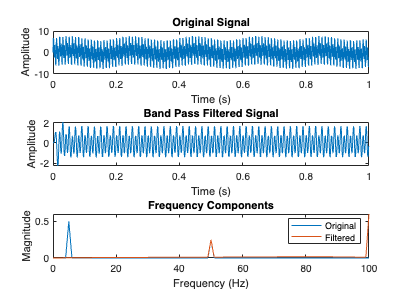

% Band pass filter design
Fc1 = 10; % Lower cutoff frequency (Hz)
Fc2 = 90; % Upper cutoff frequency (Hz)
x = sin(2*pi*5*t) + 0.5*sin(2*pi*50*t) + 3*sin(2*pi*100*t) + 5*sin(2*pi*200*t);

[b, a] = butter(6, [Fc1 Fc2]/(Fs/2), 'bandpass'); % 6th order Butterworth filter

% Apply the band pass filter
y_band = filter(b, a, x);

% FFT of the filtered signal
Y_band = fft(y_band);

% Plot the results
figure;
subplot(3,1,1);
plot(t, x);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, y_band);
title('Band Pass Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(f, abs(X)/N);
hold on;
plot(f, abs(Y_band)/N);
title('Frequency Components');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original', 'Filtered');
xlim([0 100]); % Limit frequency range for clarity

Band Stop Filter

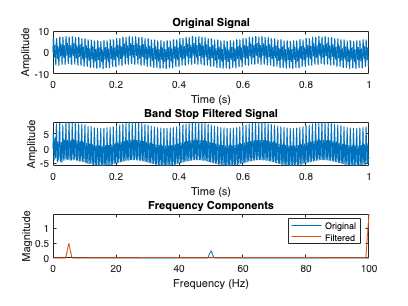

% Band stop filter design
Fc1 = 40; % Lower cutoff frequency (Hz)
Fc2 = 60; % Upper cutoff frequency (Hz)
[b, a] = butter(6, [Fc1 Fc2]/(Fs/2), 'stop'); % 6th order Butterworth filter

% Apply the band stop filter
y_stop = filter(b, a, x);

% FFT of the filtered signal
Y_stop = fft(y_stop);

% Plot the results
figure;
subplot(3,1,1);
plot(t, x);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, y_stop);
title('Band Stop Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(f, abs(X)/N);
hold on;
plot(f, abs(Y_stop)/N);
title('Frequency Components');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original', 'Filtered');
xlim([0 100]); % Limit frequency range for clarity



F = fspecial("average",n)




